## This example focuses on quality controlling seawater pCO2 from deployment #6. 

Load the data from the Pioneer Array Inshore Surface Mooring. Data has been compiled covering the period 10/11/2016 - 3/28/2018. This covers mooring deployments 5, 6, and 7. ISSM data was downloaded using the OOI provided M2M Matlab tools as netCDF files. Two data streams were downloaded ("Telemetered" and "Recovered Host"), and merged together into a single dataset for analysis. Datasets were converted to a Matlab Timetable for analysis.  

load ISSM_for_Worked_Example.mat 

%Data are in the format of at Matlab Timetable. 

ISSM(1:10,:) % Display the first 10 rows of data.

ans = 10×18 timetable
          DateTime             time       partial_pressure_co2_ssw    partial_pressure_co2_atm    pco2_co2flux    gas_stream_pressure    met_salsurf    sea_surface_temperature    zero_a2d    deployment    measured_water_co2    current_a2d    measured_water_co2_qc_results    partial_pressure_co2_ssw_qc_results    partial_pressure_co2_ssw_qartod_results    relative_humidity    air_temperature    humidity_temperature    humidity
    ____________________    __________    ________________________    ________________________    ____________    __________________

%Retime the data to hourly bins
ISSM = retime(ISSM,'hourly','mean'); 

ISSM(1:10,:) % Display the first 10 rows of data.

ans = 10×18 timetable
          DateTime             time       partial_pressure_co2_ssw    partial_pressure_co2_atm    pco2_co2flux    gas_stream_pressure    met_salsurf    sea_surface_temperature    zero_a2d    deployment    measured_water_co2    current_a2d    measured_water_co2_qc_results    partial_pressure_co2_ssw_qc_results    partial_pressure_co2_ssw_qartod_results    relative_humidity    air_temperature    humidity_temperature    humidity
    ____________________    __________    ________________________    ________________________    ____________    __________________

## Load the discrete data. 

Discrete datasets were compiled from the OOI Alfresco Server. The "Discrete Summary" files are not available for the Pioneer 6 (AR18, shown for Leg C) or Pioneer 7 (AR24, shown for Leg B) cruises, so individual data files were downloaded and compiled into a single dataset. Data files included the carbonate data, CTD cast data, and Salinity. Included in the discrete dataset shown below are the surface measurements only as those are the most relevant to the sensors of interest on the surface mooring. No data are flagged as questionable (all 2s for the flags). 

load ISSM_Discrete.mat 

bottleOOI % Display the discrete observations

bottleOOI = 4×23 table
    Station    Cruise    Cast    Niskin    DissolvedOxygenumolkg    Year    Month    Day    Hour    Minute    Second     Lat        Lon      Depth    Salinity     Temp      DIC      DICflag      TA      TAFlag      pH      pHtemp    pHFlag
    _______    ______    ____    ______    _____________________    ____    _____    ___    ____    ______    ______    ______    ____

## Load the annotations

annotations = readtable('annotations.csv')

annotations = 34×20 table
     id         category              startDate                    endDate                                                                                                          description                                                                                                  ongoing      parameter_group                                                                                                                                                                                                                                                                                                                                         links                                                                                                                                                                                           

No annotations are noted for Deployment 6. 

## Graph the initial dataset from the deployment of interest.

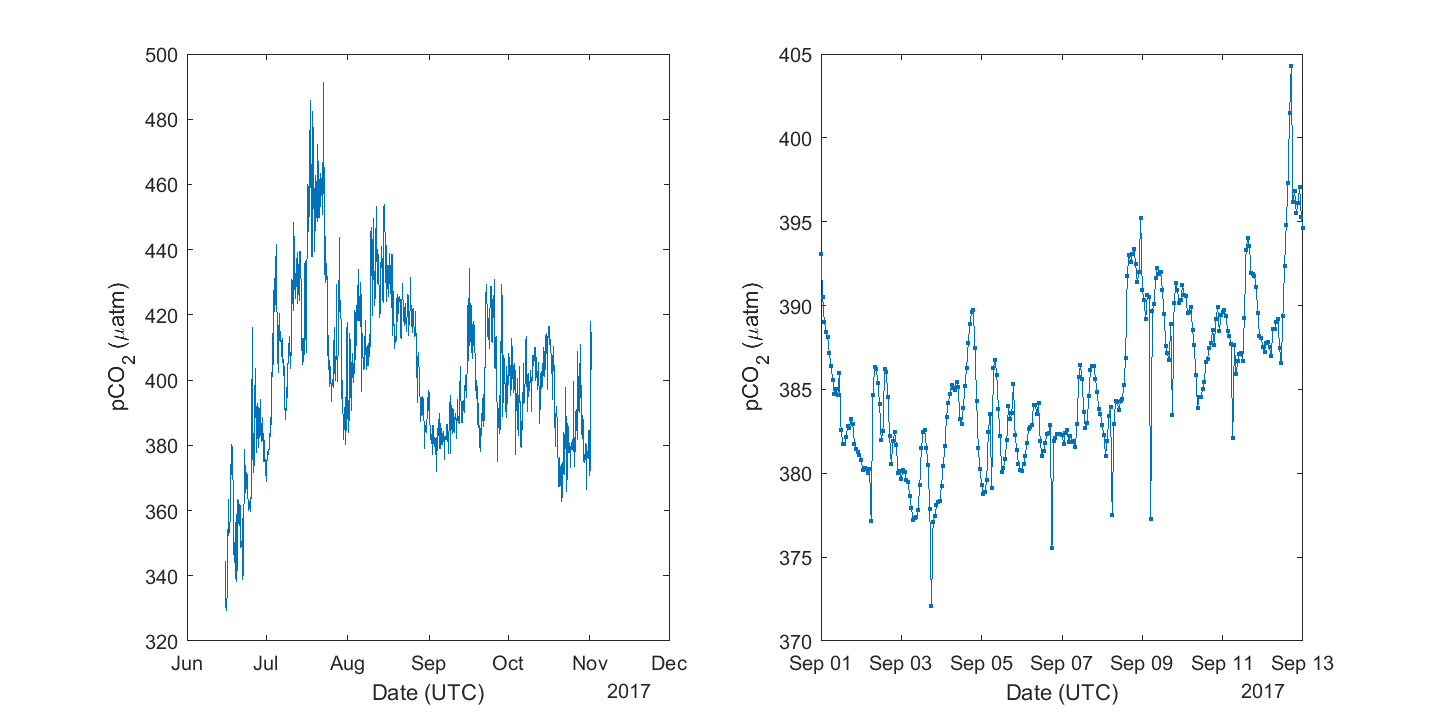

fig = figure; fig.Units = 'Inches'; fig.Position = [0 0 10 5];
subplot(121); 
plot(ISSM.DateTime(ISSM.deployment == 6),ISSM.partial_pressure_co2_ssw(ISSM.deployment == 6)); xlabel('Date (UTC)'); ylabel('pCO_2 (\muatm)');
subplot(122);
plot(ISSM.DateTime(ISSM.deployment == 6),ISSM.partial_pressure_co2_ssw(ISSM.deployment == 6),'.-'); xlabel('Date (UTC)'); ylabel('pCO_2 (\muatm)');
xlim([datetime([2017 9 1],'TimeZone','UTC') datetime([2017 9 13],'TimeZone','UTC')]);

The left panel shows the full dataset. The right panel shows a zoomed in interval from January 16, 2017 - February 4, 2017. The effects of the autozeroing function on the observations can be seen as sharp drops in the signal every 12 hours during the hours of 21:00 and 9:00. 

## Create an overall flag variable, apply the QARTOD flags, and flag the data during the autozeroing as bad.

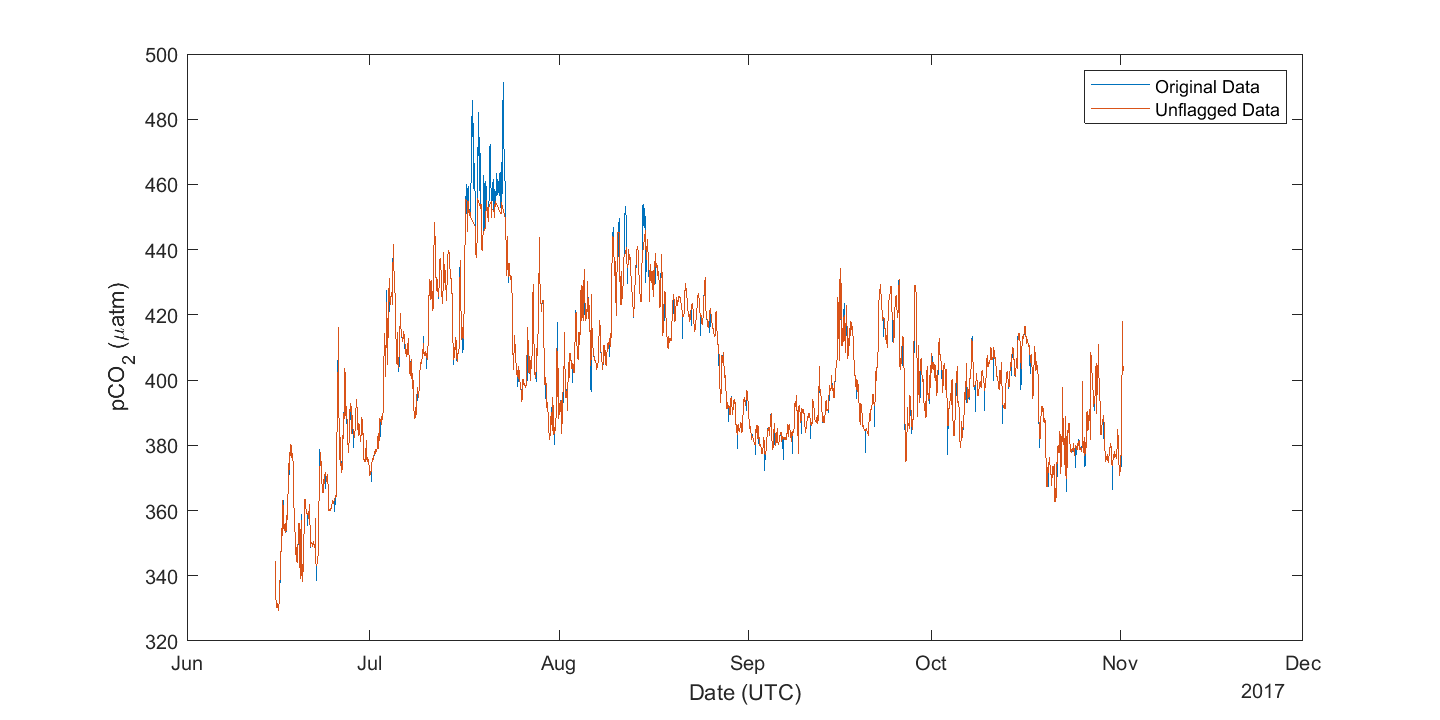

I5 = find((hour(ISSM.DateTime) == 21 | hour(ISSM.DateTime) == 9) & ISSM.deployment == 5); %autozero during deployment 5
I6 = find((hour(ISSM.DateTime) == 6 | hour(ISSM.DateTime) == 18) & ISSM.deployment == 6); %autozero during deployment 6
I7 = find((hour(ISSM.DateTime) == 7 | hour(ISSM.DateTime) == 19) & ISSM.deployment == 7); %autozero during deployment 7

ISSM.pCO2_flag = ones(height(ISSM),1).*2; %Create overall flag
ISSM.pCO2_flag(I5) = 5; ISSM.pCO2_flag(I6) = 5; ISSM.pCO2_flag(I7) = 5; % Flag autozero signal as 5 for bad data
ISSM.pCO2_flag(ISSM.partial_pressure_co2_ssw_qartod_results > 2) = 5; % Apply QARTOD flags for any questionable or bad data

fig = figure; fig.Units = 'Inches'; fig.Position = [0 0 10 5];
plot(ISSM.DateTime(ISSM.deployment == 6),ISSM.partial_pressure_co2_ssw(ISSM.deployment == 6)); xlabel('Date (UTC)'); ylabel('pCO_2 (\muatm)'); hold on;
plot(ISSM.DateTime(ISSM.pCO2_flag == 2 & (ISSM.deployment == 6)),ISSM.partial_pressure_co2_ssw(ISSM.pCO2_flag == 2 & (ISSM.deployment == 6))); 

legend('Original Data','Unflagged Data');

## Calculate the full carbonate system on the discrete sample data

p = gsw_p_from_z(-bottleOOI.Depth,bottleOOI.Lat); %calculate sea pressure from bottle sample depth.

bottleOOI.DateTime = datetime(bottleOOI{:,6:11},'TimeZone','UTC'); 


Using CO2SYS for Matlab, quantify the full carbonate system from discrete pH and DIC samples. This calculation uses carbonic acid dissociation coefficients K1 and K2 from Leuker et al. (2000), sulfate dissociation constant KSO4 from Dickson (1990), total borate concentration from Lee et al. (2010), and HF dissociation coefficient KHF from Perez and Fraga (1987) were used in carbonate system calculations. Input temperature and pressure is set to the temperature and pressure that pH samples were processed at (25 degrees celcius, 0 dbar) and output temperature and pressure was set to insitu conditions. 

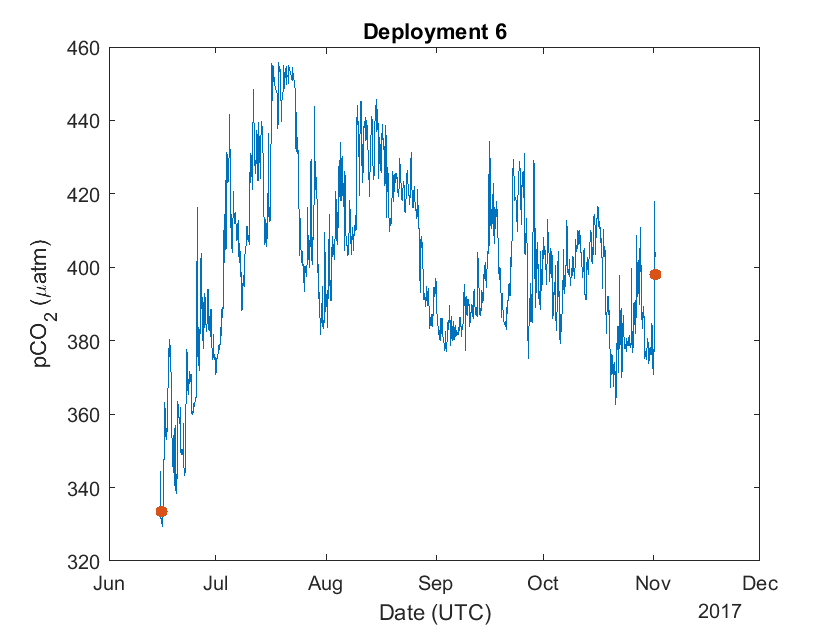


Carb = CO2SYS(bottleOOI.pH,bottleOOI.DIC,3,2,bottleOOI.Salinity,bottleOOI.pHtemp,bottleOOI.Temp,0,p,0,0,0,0,1,10,1,2,2);
Carb(Carb < -100) = nan; % eliminate -999 output


fig = figure; fig.Units = 'Inches'; fig.Position = [0 0 10 5];
plot(ISSM.DateTime(ISSM.pCO2_flag == 2 & ISSM.deployment == 6),ISSM.partial_pressure_co2_ssw(ISSM.pCO2_flag == 2 & ISSM.deployment == 6)); hold on; 
xlabel('Date (UTC)'); ylabel('pCO_2 (\muatm)'); title('Deployment 6')
scatter(bottleOOI.DateTime,Carb(:,22),'filled');

## Quantify offset between discrete observations and sensor data

G = findgroups(bottleOOI.DateTime); 
AverageCarb = splitapply(@nanmean,Carb,G); %Average duplicate samples together
SampleDate = splitapply(@nanmean,bottleOOI.DateTime,G); 
TR1 = timerange(SampleDate(1)-hours(1.5),SampleDate(1)+hours(1.5)); 
TR2 = timerange(SampleDate(2)-hours(1.5),SampleDate(2)+hours(1.5)); 

ISSM_noflag = ISSM; % Create new variable to delete bad data from
ISSM_noflag.partial_pressure_co2_ssw(ISSM.pCO2_flag > 2) = nan; % Replace all the flagged data with NaN;

X(1,1) = nanmean(ISSM_noflag.partial_pressure_co2_ssw(TR1)); %quantify mean sensor data during the 3 hour window surounding when the first discrete sample was collected
X(2,1) = nanmean(ISSM_noflag.partial_pressure_co2_ssw(TR2)); %quantify mean sensor data during the 3 hour window surounding when the second discrete sample was collected

Y = array2table(X,'VariableNames',{'partial_pressure_pco2_ssw'});
Y.discrete_pco2 = AverageCarb(:,22)

Y = 2×2 table
    partial_pressure_pco2_ssw    discrete_pco2
    _________________________    _____________

             331.51                 333.52    
              395.5                 397.97    


Sensor pCO2 (partial_pressure_pco2_ssw) and the discrete observations match remarkably well, and likely well within the expected uncertainty of the carbonate system calculations. In this scenario, no offset correction is needed. However, an example offset correction between the sensors and discrete samples is given below, for reference. 

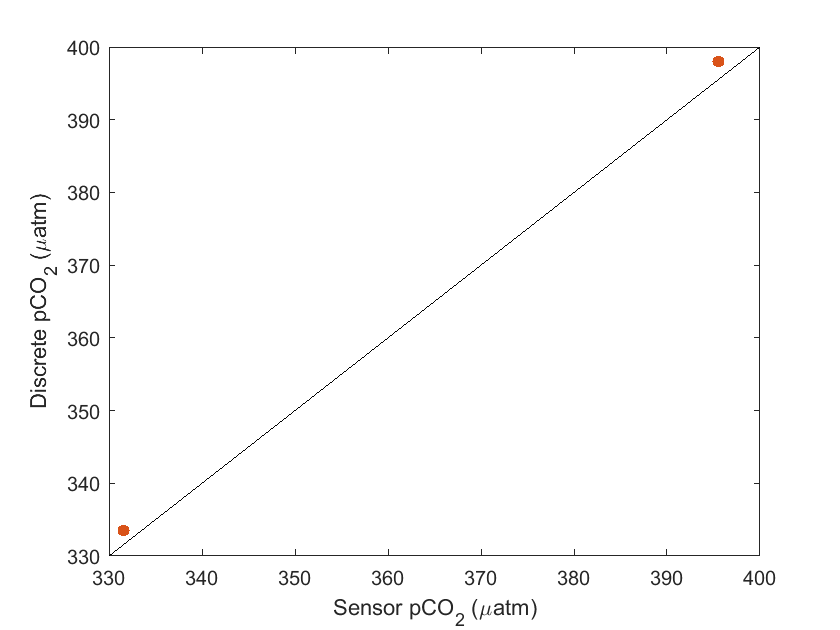

fig = figure; 
plot([330 400],[330 400],'k'); hold on; 
scatter(Y.partial_pressure_pco2_ssw,Y.discrete_pco2,'filled'); set(gca,'box','on') ;
xlabel('Sensor pCO_2 (\muatm)'); ylabel('Discrete pCO_2 (\muatm)');

This figure illustrates how the sensor data compares to the discrete data. The black line is 1-1, so a slight offset is noticable, but consistent throughtout the timeseries.  

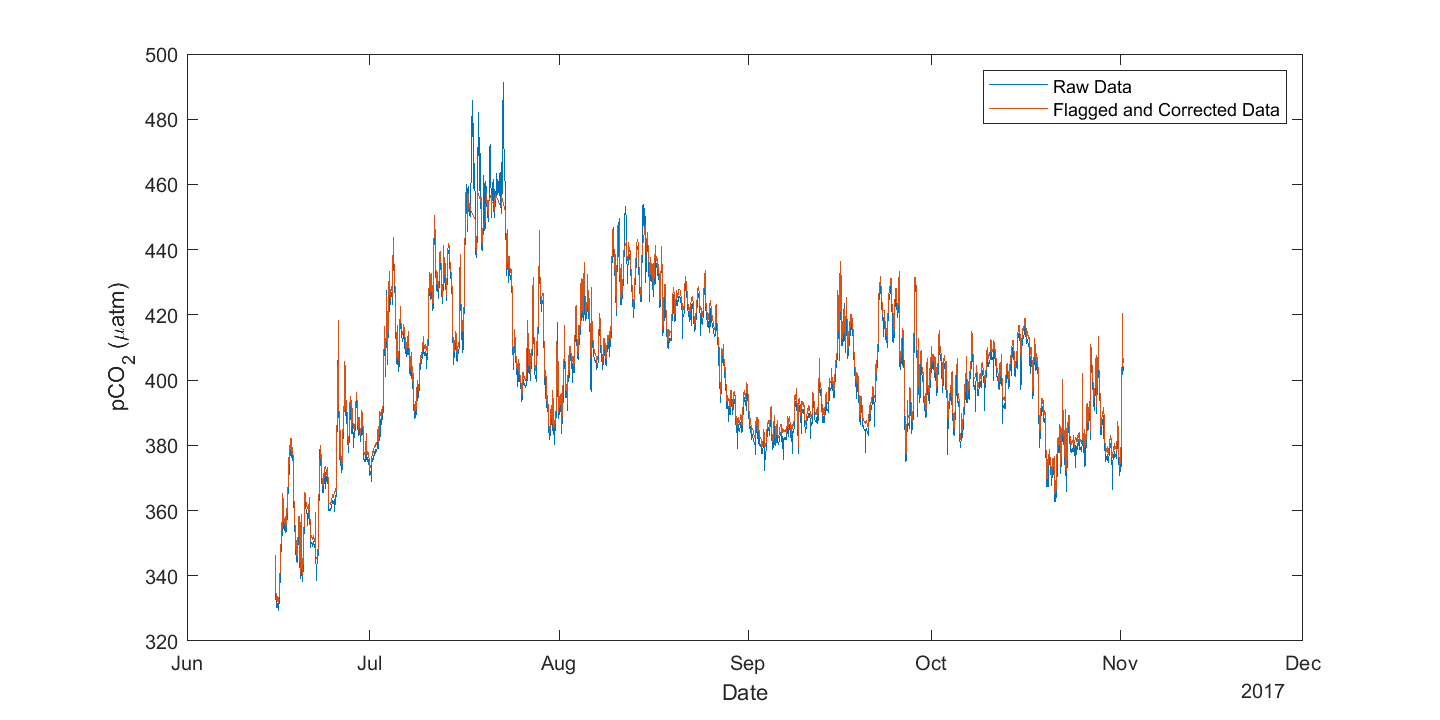

offset = Y.partial_pressure_pco2_ssw-Y.discrete_pco2; %Quantify the offset between the discrete data and the sensor data
f = fitlm(datenum(SampleDate),offset); %Use Matlab's numeric datenumber to calculate a linear drift between the two discrete observations
timeseries_offset = predict(f,datenum(ISSM.DateTime(ISSM.deployment == 6))); 
ISSM.partial_pressure_co2_ssw_Corrected = nan(height(ISSM),1); 
ISSM.partial_pressure_co2_ssw_Corrected(ISSM.deployment == 6) = ISSM.partial_pressure_co2_ssw(ISSM.deployment == 6) - timeseries_offset; 

fig = figure; fig.Units = 'Inches'; fig.Position = [0 0 10 5];
plot(ISSM.DateTime(ISSM.deployment == 6),ISSM.partial_pressure_co2_ssw(ISSM.deployment == 6)); hold on; 
plot(ISSM.DateTime(ISSM.deployment == 6 & ISSM.pCO2_flag < 3),ISSM.partial_pressure_co2_ssw_Corrected(ISSM.deployment == 6 & ISSM.pCO2_flag < 3));
xlabel('Date'); ylabel('pCO_2 (\muatm)'); legend('Raw Data','Flagged and Corrected Data');